### Critical Tipping Moment (ARL hanging-mass test + puck layout)

What this file does: at the ARL we hung a known mass off an arm attached to the ABV and increased it until the ABV tipped. This file turns those two measurements into a tipping limit for the docking hardware.

The key idea: the ABV floats on 3 air pucks, each 6 in from the center and 120° apart (GSA sketch). It does not tip about its frame edge; it tips about the line between two pucks, which is only 3 in (76 mm) from the center. Everything in this file is measured from that line. The turning effect of a weight about that line (weight x lever) is called a moment, in N·m.

How the arm was measured: it was zip-tied to the far side of the ABV and stuck out past the test edge. So the weight hung (arm length − half the ABV width) from the center. Its lever about the puck line is that distance minus 76 mm.

What changed from the last version: the old file measured levers from the frame edge, which assumed the pivot was 95 mm farther out than it really is. That overstated how much the hardware could carry (12.2 kg → 5.0 kg at the hardware location). The conclusion is unchanged: the current hardware is well inside the limit.

clear; clc; close all;

g    = 9.81;      % m/s^2, gravity
in2m = 0.0254;    % inches to meters

% ---- ABV and puck layout (GSA, Nov 2026) ----
m_abv     = 12.0;              % kg, last measured by the lab (GSA); lighter after upgrades
half_w    = 6.75 * in2m;       % m, half the ABV width (13.5 in)
R_puck    = 6 * in2m;          % m, each puck is 6 in from the ABV center, 120 deg apart
b_line    = R_puck / 2;        % m, ABV center to the line between two pucks (pivot when tipping
                               % toward a 2-puck edge; the closest pivot, so the most conservative)

% ---- ARL test measurements ----
side_names = {'Perpendicular side', 'Nitrogen tank side'};
arm_in     = [28, 26];         % in, arm length from the zip-tie point (far side of the ABV)
mass_g     = [965, 1695];      % g, hanging mass at which the ABV tipped
r_test     = arm_in * in2m - half_w;   % m, hanging weight distance from the ABV center
lever_test = r_test - b_line;          % m, lever about the puck line

mass_kg  = mass_g / 1000;
M_crit   = mass_kg * g .* lever_test;  % N*m, tipping moment about the puck line
mr_crit  = M_crit / g;                 % kg*m, same limit as mass x distance past the puck line

% ---- Current docking hardware (drogue + ABV bracket) ----
m_side   = 1.296;                      % kg, measured mass
r_side   = half_w + 0.044;             % m, hardware center of mass from the ABV center (44 mm past the front edge, CAD)
lever_hw = r_side - b_line;            % m, hardware lever about the puck line
m_tip_hw = mr_crit / lever_hw;         % kg, hardware mass that would tip the ABV

### Results

Side        = string(side_names');
TippingTest = table(Side, arm_in', r_test'*100, lever_test'*100, mass_g', M_crit', m_tip_hw', ...
    'VariableNames', {'Side', 'Arm length (in)', 'Weight from center (cm)', 'Lever past puck line (cm)', ...
                      'Mass at tip-over (g)', 'Tipping moment (N·m)', 'Hardware mass that tips it (kg)'})

TippingTest = 2×7 table
            Side            Arm length (in)    Weight from center (cm)    Lever past puck line (cm)    Mass at tip-over (g)    Tipping moment (N·m)    Hardware mass that tips it (kg)
    ____________________    _______________    _______________________    _________________________    ____________________    ____________________    _______________________________

    "Perpendicular side"          28                   53.975                      46.355                       965                   4.3883                       3.2124             
    "Nitrogen tank side"          26                   48.895                      41.275                      1695                   6.8632                       5.0241             



fprintf('The tank side is %.2f times harder to tip than the perpendicular side.\n', M_crit(2)/M_crit(1));

The tank side is 1.56 times harder to tip than the perpendicular side.


fprintf('Docking hardware (tank side): %.3f kg sitting %.0f mm past the puck line.\n', m_side, lever_hw*1e3);

Docking hardware (tank side): 1.296 kg sitting 139 mm past the puck line.


fprintf('It would take %.2f kg there to tip the ABV, so the margin is %.1fx\n', m_tip_hw(2), m_tip_hw(2)/m_side);

It would take 5.02 kg there to tip the ABV, so the margin is 3.9x


fprintf('(%.1fx even if it were mounted on the weaker perpendicular side).\n', m_tip_hw(1)/m_side);

(2.5x even if it were mounted on the weaker perpendicular side).


### Cross-check: does the puck layout explain the test?

If the ABV were a perfect 12 kg block centered over its pucks, it would resist tipping with its own weight x the distance from its center to the pivot. The table compares that ideal number with what the ARL test measured. The measured values are lower because the steel test arm adds its own weight and the ABV center of mass is not exactly over the puck center. We use the measured (lower, safer) values for every decision.

face  = ["Toward a 2-puck edge"; "Sideways"; "Toward the single puck"];
b_dir = [b_line; b_line/cosd(30); R_puck];                 % m, distance from center to the pivot in that direction
M_ideal = m_abv * g * b_dir;                               % N*m
m_ideal = m_abv * b_dir ./ (r_side - b_dir);               % kg of hardware at r_side that would tip an ideal ABV
PuckModel = table(face, b_dir*1e3, M_ideal, m_ideal, ...
    'VariableNames', {'Docking face points', 'Pivot distance (mm)', 'Ideal tipping moment (N·m)', ...
                      'Hardware mass that tips it (kg)'})

PuckModel = 3×4 table
      Docking face points       Pivot distance (mm)    Ideal tipping moment (N·m)    Hardware mass that tips it (kg)
    ________________________    ___________________    __________________________    _______________________________

    "Toward a 2-puck edge"              76.2                     8.9703                          6.5666             
    "Sideways"                        87.988                     10.358                          8.2837             
    "Toward the single puck"           152.4                     17.941                          29.006             


fprintf('Measured tipping moments are %.0f%% and %.0f%% of the ideal 2-puck-edge value.\n', ...
    100*M_crit(1)/M_ideal(1), 100*M_crit(2)/M_ideal(1));

Measured tipping moments are 49% and 77% of the ideal 2-puck-edge value.


fprintf('Pointing the docking face at the single puck is about %.0fx stronger than at a 2-puck edge,\n', m_ideal(3)/m_ideal(1));

Pointing the docking face at the single puck is about 4x stronger than at a 2-puck edge,


fprintf('but the current hardware is far below the limit either way, so the mounting side is not critical.\n');

but the current hardware is far below the limit either way, so the mounting side is not critical.


### Plots

Left: the puck layout seen from above, with the pivot lines. Right: the heaviest hardware the ABV can carry at a given distance past its front edge before it tips. The star is the current docking hardware.

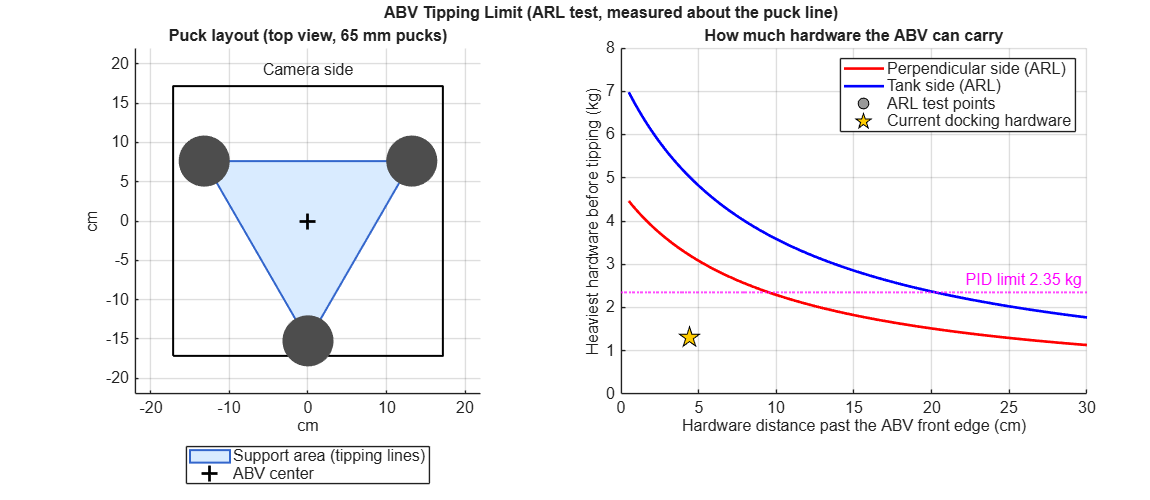

fig = figure('Name', 'Critical Tipping Moment', 'Position', [100 100 1150 500]);
theme(fig, 'light');
tl = tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on; axis equal;
sq = half_w*100*[-1 1 1 -1 -1; -1 -1 1 1 -1];
plot(sq(1,:), sq(2,:), 'k-', 'LineWidth', 1.5, 'HandleVisibility', 'off');
ang = [30 150 270];
P = R_puck*100*[cosd(ang); sind(ang)];
fill(P(1,[1 2 3 1]), P(2,[1 2 3 1]), [0.85 0.92 1], 'EdgeColor', [0.2 0.4 0.8], 'LineWidth', 1.5, ...
    'DisplayName', 'Support area (tipping lines)');
th = linspace(0, 2*pi, 40);
for k = 1:3
    fill(P(1,k) + 3.25*cos(th), P(2,k) + 3.25*sin(th), [0.3 0.3 0.3], 'EdgeColor', 'none', 'HandleVisibility', 'off');
end
plot(0, 0, 'k+', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'ABV center');
text(0, half_w*100 + 2, 'Camera side', 'HorizontalAlignment', 'center');
xlabel('cm'); ylabel('cm'); title('Puck layout (top view, 65 mm pucks)');
xlim([-22 22]); ylim([-22 22]); grid on; legend('Location', 'southoutside');

nexttile; hold on;
d_edge = linspace(0.005, 0.30, 200);                 % m past the front edge
lev = half_w + d_edge - b_line;
plot(d_edge*100, mr_crit(1)./lev, 'r-', 'LineWidth', 2, 'DisplayName', 'Perpendicular side (ARL)');
plot(d_edge*100, mr_crit(2)./lev, 'b-', 'LineWidth', 2, 'DisplayName', 'Tank side (ARL)');
plot((r_test - half_w)*100, mass_kg, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', [0.6 0.6 0.6], 'DisplayName', 'ARL test points');
plot(0.044*100, m_side, 'kp', 'MarkerSize', 16, 'MarkerFaceColor', [1 0.8 0], 'DisplayName', 'Current docking hardware');
yline(2.35, 'm:', 'PID limit 2.35 kg', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'right');
xlabel('Hardware distance past the ABV front edge (cm)');
ylabel('Heaviest hardware before tipping (kg)');
title('How much hardware the ABV can carry');
ylim([0 8]); xlim([0 30]); grid on; legend('Location', 'northeast');

title(tl, 'ABV Tipping Limit (ARL test, measured about the puck line)', 'FontWeight', 'bold');
fontsize(fig, 12, 'points');

### Notes

Which way the docking face points relative to the pucks is not yet confirmed. The limits above use the closest pivot line (76 mm), which is the most conservative case. If the face points at the single puck, the real limit is higher.